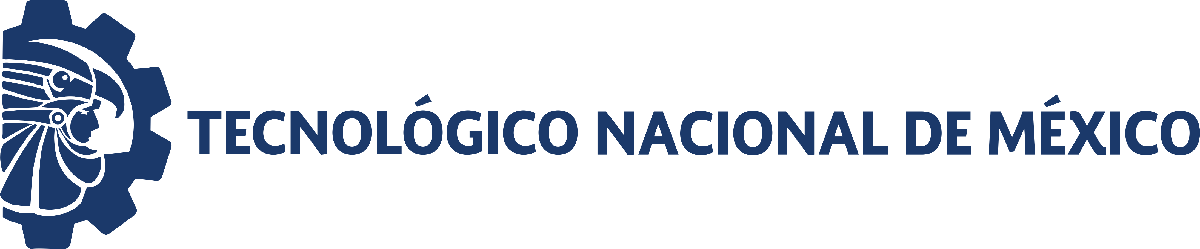                                 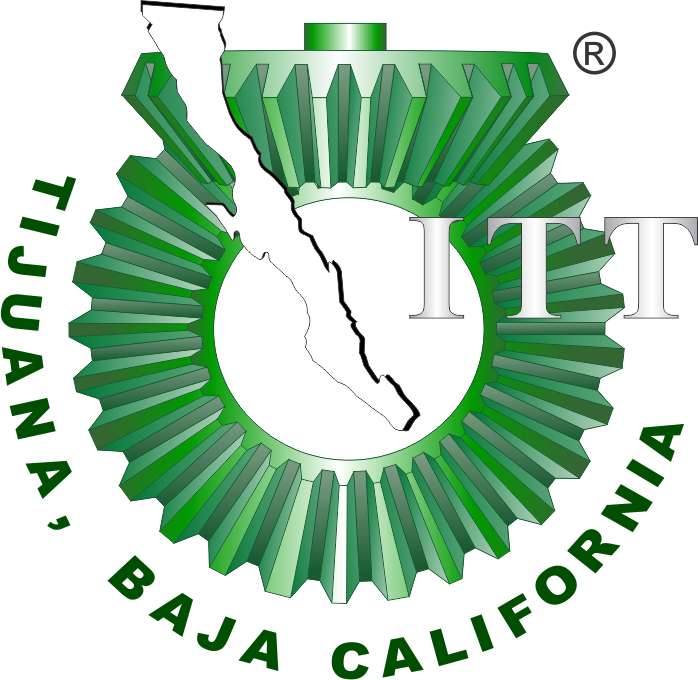

# Proyecto: Sistema renal

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

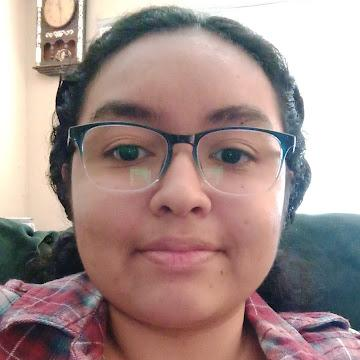

Nombre del alumno: **Tchandra Yahoel Camacho Llanes**

Número de control: **19212376**

Correo institucional: **L19212376@tectijuana.edu.mx**

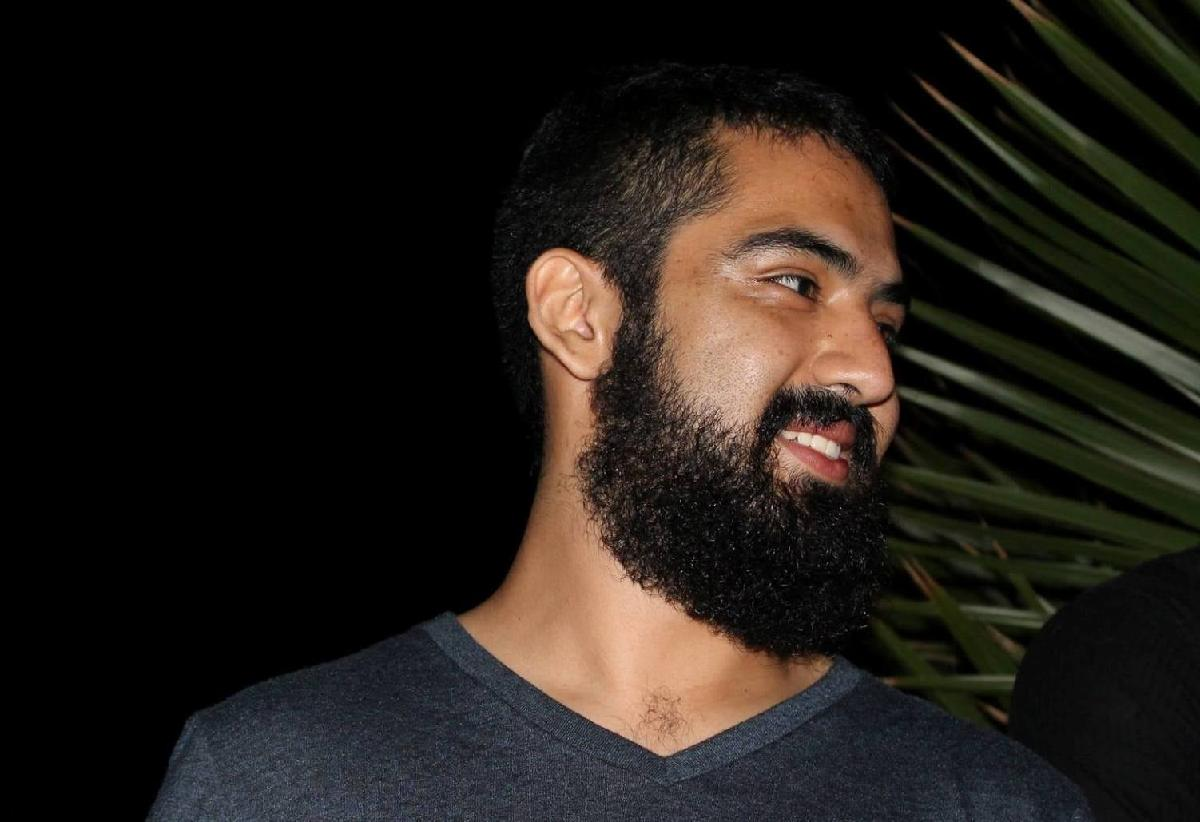

Nombre del alumno: **Victor Silvano Dino Seañez**

Número de control: **20211964**

Correo institucional: **L20211964@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
file = 'Sistema';
open_system(file);
parameter.StopTime = '15';
parameter.Solver = 'ode15s';
parameter.MaxStep = '1E-3';
x = sim(file,parameter);

## Respuesta del sistema

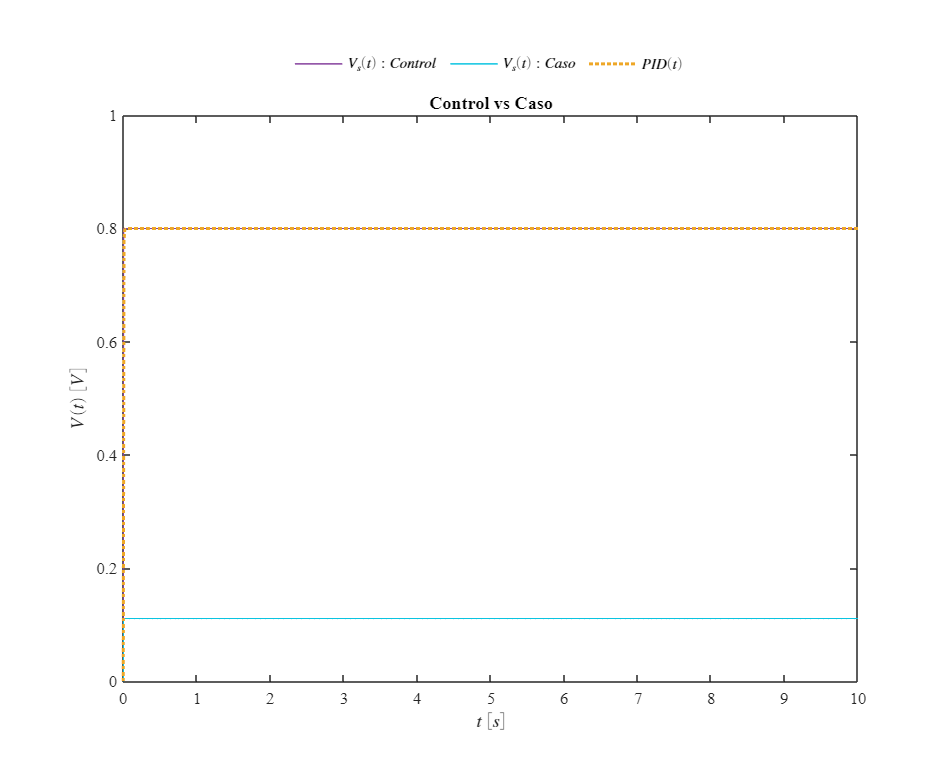

plotsignals(x.t,x.Vs1,x.Vs4,x.PID)

## Funcion: Respuesta del sistema

function plotsignals(t,Vs1,Vs4,PID)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,25,20])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    
    powerrangers = [133,64,157;
                   10,196,224;
                   238,167,39]/255;
    colororder(powerrangers)

    P = plot(t,Vs1,'-',t,Vs4,'-',t,PID,':','LineWidth',1); set (P(3),'LineWidth',2)
    L = legend('$V_s(t):Control$','$V_s(t):Caso$','$PID(t)$');
    set(L,'Interpreter','Latex','FontSize',10,'location',...
        'NorthOutside','box','off','Orientation','Horizontal')

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$V(t)$ $[V]$','Interpreter','Latex','FontSize',11)
    xlim([0,10]); xticks(0:1:10);
    ylim([0,1]); yticks(0:0.2:1)
    T = title("Control vs Caso"); set(T,'FontSize',10);
    set(gca,'FontName','Time News Roman','FontSize',11)


    exportgraphics(gcf,'s_renal.pdf','ContentType','vector')
    %exportgraphics(gcf,[Signal,'.png'],'Resolution',600);
    %print(Signal,'-dsvg','-r600');
    %print(Signal,'-depsc','-r600')

end